## Spatial Analysis

L = 0.01;
N_L = 100;
mu_0 = pi*4e-7;
eps_0 = 8.85418782e-12;
omega = 2*pi*(10^(10));
Z_L = 0.7e2;
vp = 0.15e8;
z = linspace(0, L, N_L);

**Derived Solution**

E = (omega/vp);


$$\Gamma(z)=\frac12 e^{-\omega/v_p z}$$


Gamma = 0.5.*(1-exp(-E.*z));
dGamma = 0.5.*(E)*exp(-E.*z);

Plotting Gamma

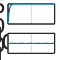

figure
subplot(2,1,1)
plot(z, abs(Gamma))
grid("on")
xlabel("z[m]")
ylabel("abs \Gamma(z)")
title("Gamma")
subplot(2,1,2)
plot(z, angle(Gamma))
grid("on")
xlabel("z[m]")
ylabel("angle \Gamma(z)")


$$\epsilon(z)=\left(\frac1{\displaystyle I(L)\frac{Z_L}{\sqrt\mu_0}I^{-1}(z)+I^{-1}(z)\int_L^zI(x)b(x)dx}\right)^2$$


a = -2*dGamma.*(1./(1-Gamma.^2));
b = 4*1j*omega*sqrt(mu_0)*(Gamma./(1-Gamma.^2));

Integrating Factor $I(z)=e^{\int_L^z-a(x)dx}$

% Numerically integrate a from L to z
int_a = cumtrapz(a)*(L/N_L) - trapz(a)*(L/N_L);

% Calculate I(z)
I = exp(-int_a);
D = cumtrapz(I.*b)*(L/N_L) - trapz(I.*b)*(L/N_L);

Plotting $\epsilon(z)$

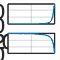

eps = ( I(N_L)*(Z_L/sqrt(mu_0))*I.^(-1) + I.^(-1).*D ).^(-2);
figure
subplot(2,1,1)
plot(z, abs(eps/(eps_0)))
grid("on")
xlabel("z[m]")
ylabel("abs \epsilon_r(z)")
title("\epsilon_r(z)")
subplot(2,1,2)
plot(z, angle(eps/(eps_0)))
grid("on")
xlabel("z[m]")
ylabel("angle \epsilon_r(z)")

## ode45

clear z;
Gamma = @(z)0.5*(1-exp(-E.*z));
dGamma = @(z)0.5*(E)*exp(-E.*z);
a = @(z) -2*dGamma(L-z).*(1./(1-Gamma(L-z).^2));
b = @(z) 4*1j*omega*sqrt(mu_0).*(Gamma(L-z)./(1-Gamma(L-z).^2));

ODE is $\xi'(z)+a(z)\xi(z)+b(z)\xi^2(z)=0$

`Let `$z_r=L-z$`. Then we have`


$$\xi'(L-z_r)+a(L-z_r)\xi(L-z_r)+b(L-z_r)\xi^2(L-z_r)=0$$


`Define `$\xi(L-z_r)=\xi_r(z_r)$`, `$a(L-z_r)=a_r(z_r)$`, and `$b(L-z_r)=b_r(z_r)$

`We solve for `$\xi_r(z_r)$` and by substition we have`


$$-\xi_r'(z_r)+a_r(z_r)\xi_r(z_r)+b_r(z_r)\xi_r(z_r)^2=0$$


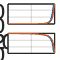

odefun = @(z, v) -a(z)*v - b(z);
[z, v] = ode45(odefun, [0, L], (Z_L/sqrt(mu_0))^(1));
eps_ode = flip((1./v).^2);

figure
subplot(2,1,1)
plot(z, abs(eps_ode/(eps_0)))
hold on
plot(linspace(0, L, N_L), abs(eps/(eps_0)))
grid("on")
xlabel("z[m]")
ylabel("abs \epsilon_r(z)")
title("\epsilon_r(z)")
subplot(2,1,2)
plot(z, angle(eps_ode/(eps_0)))
hold on
plot(linspace(0, L, N_L), angle(eps/(eps_0)))
grid("on")
xlabel("z[m]")
ylabel(" angle \epsilon_r(z)")

## Temporal Analysis

clear Gamma dGamma
T = 1e-10;
N_T = 100;
t = linspace(0, T, N_T);

**Derived Solution**

F = omega;


$$\Gamma(t)=\frac12-\frac12 te^{-\omega t}$$


Gamma = 0.5-0.5*t.*exp(-F.*t);
dGamma = -0.5*exp(-F.*t) - 0.5*(-F)*exp(-F.*t);

Plot of Gamma

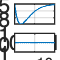

figure
subplot(2,1,1)
plot(t, abs(Gamma))
grid("on")
xlabel("t[s]")
ylabel("abs \Gamma(t)")
title("Gamma")
subplot(2,1,2)
plot(t, angle(Gamma))
grid("on")
xlabel("t[s]")
ylabel("angle \Gamma(t)")


$$\epsilon(t)=\left(\frac1{\displaystyle I(0)\frac1{\xi(0)}I^{-1}(t)+I^{-1}(t)\int_0^t-I(\tau)b(\tau)d\tau}\right)^2$$


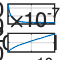

a = -2*dGamma.*(1./(1-Gamma.^2));
b = 4*1j*omega*sqrt(mu_0)*(Gamma./(1-Gamma.^2));

% Numerically integrate a from L to z
int_a = cumtrapz(a)*(T/N_T) - cumtrapz(a(1))*(T/N_T);

% Calculate I(z)
I = exp(int_a);
D = cumtrapz(I.*b)*(T/N_T) - cumtrapz(I(1)*b(1))*(T/N_T);
eps = ( I(1)*(1/(5*sqrt(eps_0)))*I.^(-1) - I.^(-1).*D ).^(-2);

figure
subplot(2,1,1)
plot(t, abs(eps/(eps_0)))
grid("on")
xlabel("t[s]")
ylabel("abs \epsilon_r(t)")
title("\epsilon_r(t)")
subplot(2,1,2)
plot(t, angle(eps/(eps_0)))
grid("on")
xlabel("t[s]")
ylabel("angle \epsilon_r(t)")

### ode45

clear t;
Gamma = @(t) 0.5-0.5*exp(-F*t);
dGamma = @(t) -0.5*(-F)*exp(-F*t);
a = @(t) -2.*dGamma(t).*(1./(1-Gamma(t).^2));
b = @(t) 4*1j*omega*sqrt(mu_0).*(Gamma(t)./(1-Gamma(t).^2));

ODE is

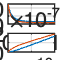

odefun = @(t, v) -a(t)*v - b(t);
[t, v] = ode45(odefun, [0, 1e-10], (5*sqrt(eps_0))^(-1));
eps_ode = (1./v).^2;

figure
subplot(2,1,1)
plot(t, abs(eps_ode/(eps_0)))
hold on
plot(linspace(0, T, N_T), abs(eps/(eps_0)))
grid("on")
xlabel("t[s]")
ylabel("abs \epsilon_r(t)")
title("\epsilon_r(t)")
subplot(2,1,2)
plot(t, angle(eps_ode/(eps_0)))
hold on
plot(linspace(0, T, N_T), angle(eps/(eps_0)))
grid("on")
xlabel("t[s]")
ylabel("angle \epsilon_r(t)")